% E8.1
clear all
syms s w
K = 10;

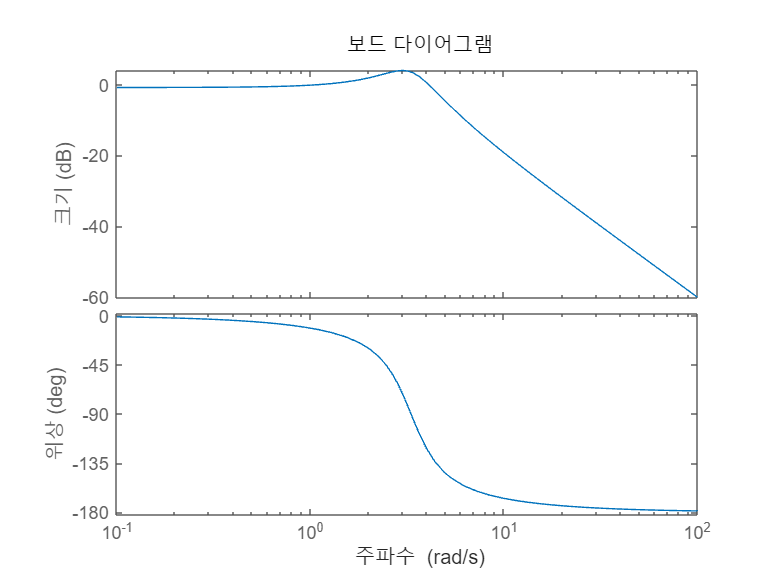

Ls = K/(s+1)^2;
Ts = Ls/(1+Ls);
[n d] = numden(Ts);
num = sym2poly(n);
den = sym2poly(d);
sys = tf(num, den);
bode(sys)

Lw = subs(Ls,s,j*w);
simplify(Lw)

$$ans = \frac{10}{{\left(1+w\,\mathrm{i}\right)}^{2}}$$

[n d] = numden(Ls);
num = sym2poly(n);
den = sym2poly(d);
sys_Ls = tf(num, den);

k = [0 0.5 1 2 4 inf];
for c = k
    [pro, deg] = bode(sys_Ls,c);
    rad = deg2rad(deg);
    fprintf("w = %.1f 일 때  크기 : %4.3f  위상 : %4.3f[rad] \n", [c pro rad])
end

w = 0.0 일 때  크기 : 10.000  위상 : 0.000[rad] 
w = 0.5 일 때  크기 : 8.000  위상 : -0.927[rad] 
w = 1.0 일 때  크기 : 5.000  위상 : -1.571[rad] 
w = 2.0 일 때  크기 : 2.000  위상 : -2.214[rad] 
w = 4.0 일 때  크기 : 0.588  위상 : -2.652[rad] 
w = Inf 일 때  크기 : 0.000  위상 : -3.142[rad] 
